clear 

% W203
W203_4Dir = './W203_4';
W203_5Dir = './W203_5';
% C12_1 10 序列
C12_1_4Dir = './C12_1_4';
C12_1_5Dir = './C12_1_5';
% C12_2 10 序列
C12_2_4Dir = './C12_2_4';
C12_2_5Dir = './C12_2_5';

DirName = C12_2_4Dir;
FileTable = GetMATFile(DirName,0); 
Nfile = size(FileTable,1); 

Ntype  = 4;
Nvalue = 10;
AnalysisData = zeros(Nfile*Ntype,Nvalue);

for iFile = 1:Nfile
    FileName = FileTable(iFile,:);
    % Point Num Aver Median Std Max Min CI_Upper CI_lower
    AnalysisData((iFile - 1) * Ntype + 1: iFile * Ntype,:) = Analysis(DirName,FileName);
end

FileName = '03_01.mat'

ans = 	1.0e+04 *

   0.0008 + 0.0000i
   0.0008 + 0.0000i
   0.0008 + 0.0000i
   0.0002 + 1.2049i


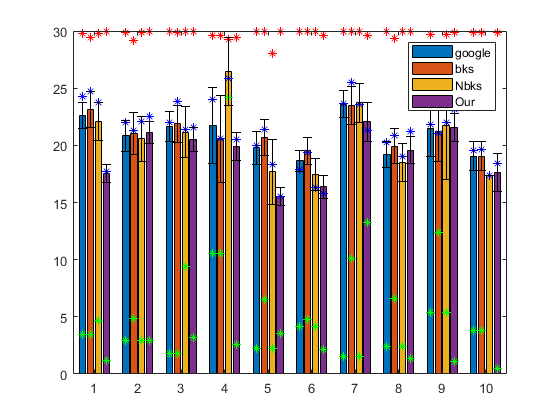

% Point Num Aver Median Std Max Min CI_Upper CI_lower
jIndex = {1 2 3 4 5 6 7 8 9 10 11};
[jPoint, jNum, jAver, jMed, jStd, jMax, jMin, jCI_Upper, jCI_lower, jHdop] = jIndex{:};

x=1:Nfile;
figure
PlotAnalysisDataAver = reshape(AnalysisData(:,jAver),Ntype,[])';
b = bar([1:Nfile], PlotAnalysisDataAver(:,:));
xbar = [b(1).XEndPoints' b(2).XEndPoints' b(3).XEndPoints' b(4).XEndPoints'];
hold on

p1=plot(xbar, reshape(AnalysisData(:,jMax),Ntype,[])','r*');
p2=plot(xbar, reshape(AnalysisData(:,jMin),Ntype,[])','g*');
p3=plot(xbar, reshape(AnalysisData(:,jMed),Ntype,[])','b*');

errorbar(xbar,reshape(AnalysisData(:,jAver),Ntype,[])', ...
    reshape(AnalysisData(:,jCI_lower),Ntype,[])' - reshape(AnalysisData(:,jAver),Ntype,[])', ...
    reshape(AnalysisData(:,jCI_Upper),Ntype,[])'-reshape(AnalysisData(:,jAver),Ntype,[])',...
    'black','Linestyle', 'None');
legend([b(1) b(2) b(3) b(4)],{'google','bks','Nbks','Our'});
% legend(p2,'Max');

hold off


% hdop
figure
b = bar([1:Nfile],reshape(AnalysisData(:,jHdop),Ntype,[])');

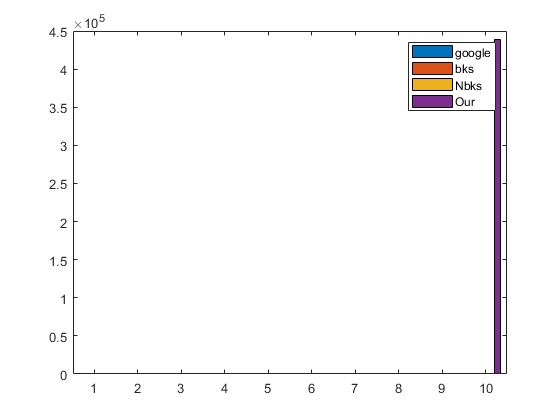

legend([b(1) b(2) b(3) b(4)],{'google','bks','Nbks','Our'});

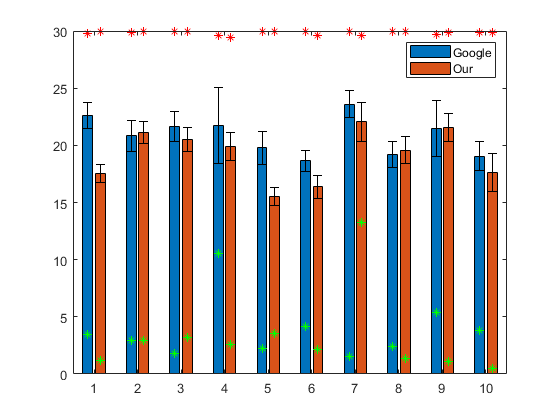

PlotSerial = [1 4]; % Google Our
% PlotFile   = [4 5 6 8 9 14 17 21 29 32 33];
PlotFile   = 1:Nfile;

% Point Num Aver Median Std Max Min CI_Upper CI_lower
jIndex = {1 2 3 4 5 6 7 8 9 10 11};
[jPoint, jNum, jAver, jMed, jStd, jMax, jMin, jCI_Upper, jCI_lower, jHdop] = jIndex{:};

x=1:length(PlotFile);
figure
PlotAnalysisDataAver = reshape(AnalysisData(:,jAver),Ntype,[])';
PlotAnalysisDataAver = PlotAnalysisDataAver(PlotFile, PlotSerial) ;
b = bar(x, PlotAnalysisDataAver);
xbar = [b(1).XEndPoints' b(2).XEndPoints'];
hold on


PlotAnalysisDataMax = reshape(AnalysisData(:,jMax),Ntype,[])';
PlotAnalysisDataMin = reshape(AnalysisData(:,jMin),Ntype,[])';
PlotAnalysisDataMed = reshape(AnalysisData(:,jMed),Ntype,[])';
PlotAnalysisDataMax = PlotAnalysisDataMax(PlotFile, PlotSerial) ;
PlotAnalysisDataMin = PlotAnalysisDataMin(PlotFile, PlotSerial) ;
PlotAnalysisDataMed = PlotAnalysisDataMed(PlotFile, PlotSerial) ;

p1=plot(xbar, PlotAnalysisDataMax,'r*');
p2=plot(xbar, PlotAnalysisDataMin,'g*');
% p3=plot(xbar, PlotAnalysisDataMed(:,[1 4]),'b*');


PlotAnalysisDataCI_lower = reshape(AnalysisData(:,jCI_lower),Ntype,[])';
PlotAnalysisDataCI_Upper = reshape(AnalysisData(:,jCI_Upper),Ntype,[])';
PlotAnalysisDataCI_lower = PlotAnalysisDataCI_lower(PlotFile, PlotSerial) ;
PlotAnalysisDataCI_Upper = PlotAnalysisDataCI_Upper(PlotFile, PlotSerial) ;

errorbar(xbar,PlotAnalysisDataAver, ...
    PlotAnalysisDataCI_lower - PlotAnalysisDataAver, ...
    PlotAnalysisDataCI_Upper - PlotAnalysisDataAver,...
    'black','Linestyle', 'None');
legend([b(1) b(2)],{'Google','Our'});

hold off